# pix2pix - Image to Image Translation

## Installation

Run the function `install.m` to ensure that all required files are added to the MATLAB path.

install();

## Training the model

To train a model you need many pairs of images of "before" and "after". The classic example is the [facades dataset](http://cmp.felk.cvut.cz/~tylecr1/facade/) which contains label images of the fronts of buildings, and the corresponding original photo.

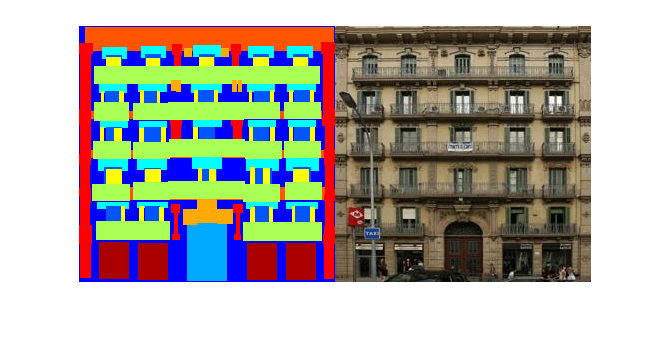

exampleInput = imread("docs/labels.png");
exampleTarget = imread("docs/target.jpg");
imshowpair(exampleInput, exampleTarget, "montage");

Use the helper function `p2p.util.downloadFacades` to download and prepare the dataset for model training. Once that's ready you will have two folders 'A' the input labels, and 'B' the desired output images. 

To train the model we need to provide the locations of the A and B images, as well as any training options, and the model will try and learn to convert A images into B images!

% [labelFolder, targetFolder] = p2p.util.downloadFacades();
labelFolder='CelebA_Line';
targetFolder='CelebA-HQ-img';

We will just use the default options which approximately reproduce the setttings from the original pix2pix paper.

options = p2p.trainingOptions('MaxEpochs',3);

Note training the model will take several hours on a GPU and requires around 6GB of GPU memory.

p2pModel = p2p.train(labelFolder, targetFolder, options);

epoch: 1, it: 50, G: 46.436607 (L1: 0.455146, GAN: 0.922058), D: 0.484929
epoch: 1, it: 100, G: 42.682575 (L1: 0.414970, GAN: 1.185540), D: 0.335106
epoch: 1, it: 150, G: 40.638557 (L1: 0.392085, GAN: 1.430088), D: 0.240146
epoch: 1, it: 200, G: 24.378460 (L1: 0.232913, GAN: 1.087128), D: 0.317003
epoch: 1, it: 250, G: 53.449963 (L1: 0.522647, GAN: 1.185253), D: 0.454613
epoch: 1, it: 300, G: 39.830830 (L1: 0.381387, GAN: 1.692115), D: 0.205338
epoch: 1, it: 350, G: 48.243729 (L1: 0.462279, GAN: 2.015847), D: 0.186587
epoch: 1, it: 400, G: 61.365883 (L1: 0.592110, GAN: 2.154927), D: 0.142191
epoch: 1, it: 450, G: 31.890642 (L1: 0.295605, GAN: 2.330168), D: 0.394909
epoch: 1, it: 500, G: 38.417336 (L1: 0.367165, GAN: 1.700828), D: 0.265218
epoch: 1, it: 550, G: 38.368717 (L1: 0.359562, GAN: 2.412520), D: 0.102165
epoch: 1, it: 600, G: 33.521603 (L1: 0.314488, GAN: 2.072829), D: 0.146543


## Generating images

Once the model is trained we can use the generator to make generate a new image. 

**Note:** The generator network expects the input image to have dimensions which are a multiple of 256 due to the down/up sampling methods. Our example image is already the right size, but if you wanted to resize an image to have appropriate dimensions be careful to use the correct resizing method for label images.

exampleInput = imresize(exampleInput, [256, 256], "Method", "nearest");

We can then use the `p2p.translate` function to convert the input image using trained model.

exampleOutput = p2p.translate(p2pModel, exampleInput);
imshowpair(exampleInput, exampleOutput, "montage");

*Copyright 2020 The MathWorks, Inc.*